# Convolutional neural nets

## Fetch images from dataset

images = fetch_images();
n_images = size(images, 1);

## Assign images to the A matrix (Mx50x50x3)

A_prev = images;

## Initialize the weight matrix with random values

% Number of filters
n_filters = 10;
% Weight matrix
W = rand(5, 5, 3, n_filters);
% bias matrix
b = ones(1, 1, 1, n_filters);

pad = 1;
stride = 5;

learning_rate = 0.01;
num_iterations = 5;

errors = zeros(num_iterations, 1);

## Pass the images through the first convolutional layer (Mx50x50x3) => (Mx10x10x10)

[convoluted_images, conv1_A_prev, conv1_W, conv1_b, conv1_stride, conv1_pad] = forward_prop_conv(A_prev, W, b, stride, pad);

## Average pooling (Mx10x10x10) => (Mx5x5x10)

[pooled_images, m_pool, n_H_pool, n_W_pool, n_C_pool] = pooling(convoluted_images, 2, 2);

## Flatten (Mx5x5x10) => (Mx250)

flattened = zeros(size(pooled_images, 1), size(pooled_images, 2)*size(pooled_images, 3)*size(pooled_images, 4));

for i=1:size(pooled_images, 1)
    flattened(i, :) = reshape(squeeze(pooled_images(i, :, :, :)), [size(pooled_images, 2)*size(pooled_images, 3)*size(pooled_images, 4), 1]);
end

## Feed forward neural networks (Mx250 => Mx50 => Mx1)

first_layer_size = 250;
second_layer_size = 50;

Y = [0; 1; 1];

% First weight matrix
W0_1 = rand(first_layer_size, second_layer_size);

% Second weight matrix
W1_2 = rand(second_layer_size, 1);

% Total number of iterations
iterations = 60000;

% Error vector for plotting
errors = zeros(iterations, 1);

for iter=1:iterations
    layer_0 = flattened;
    layer_1 = sigmoid(layer_0 * W0_1, 0);
    layer_2 = sigmoid(layer_1 * W1_2, 0);
    
    layer_2_error = Y - layer_2;
    layer_2_delta = layer_2_error .* sigmoid(layer_2, 1);
    
    layer_1_error = layer_2_delta * W1_2';
    layer_1_delta = layer_1_error .* sigmoid(layer_1, 1);

    W0_1 = W0_1 + flattened' * layer_1_delta;
    W1_2 = W1_2 + layer_1' * layer_2_delta;
    
    if(mod(iter, 10000) == 0)
        disp(mean(abs(layer_2_error)));
    end
    errors(iter, 1) = abs(sum(layer_1_error, 'all'));
    errors(iter, 2) = abs(sum(layer_2_error, 'all'));
end

   4.5658e-05

   2.3567e-05

   1.5913e-05

   1.1755e-05

   1.0770e-05

   7.8142e-06



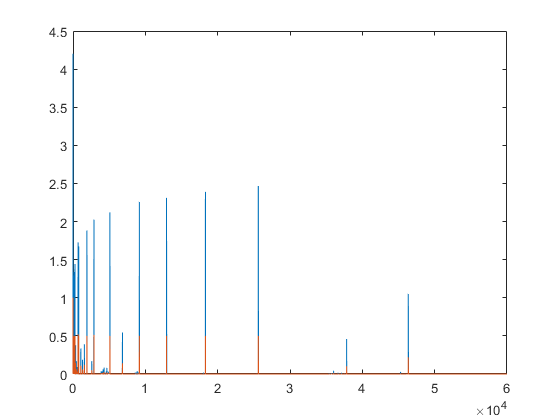


plot(errors)